%% Load immage in matlab tree.png = img1, i235.png = img2 

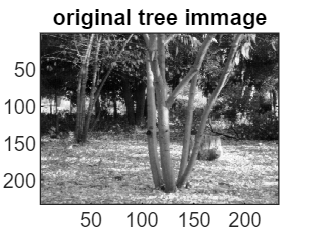

img1 = imread ("tree.png");
img2 = imread ("i235.png");

figure, imagesc(img1), colormap gray, title("original tree immage")

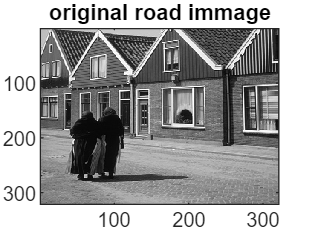



figure, imagesc(img2), colormap gray, title("original road immage")

## apply gaussian noise with standandard deviation 20

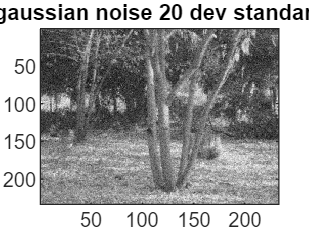

gaussian_img1 = double(img1)+20*randn(size(img1));%20 is the standard deviation
gaussian_img2 = double(img2)+20*randn(size(img2));

figure, imagesc(gaussian_img1),colormap gray, title("gaussian noise 20 dev standard")

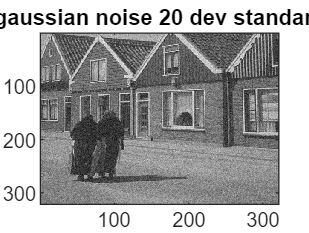

figure, imagesc(gaussian_img2),colormap gray, title("gaussian noise 20 dev standard")


## salt&pepper distibution density 20%

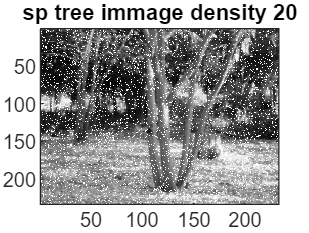

%Salt and pepper image1

img1 = double(img1);
[rr,cc]=size(img1);
maxv=max(max(img1));
indices=full(sprand(rr,cc,0.2));%0.2 is the noise density 

mask1=indices>0 & indices<0.5;  
mask2=indices>=0.5;%matlab masking technique

sp_img1 = img1.*(~mask1) ;
sp_img1 = img1.*(~mask2)+maxv*mask2;

figure, imagesc(sp_img1),colormap gray, title("sp tree immage density 20")

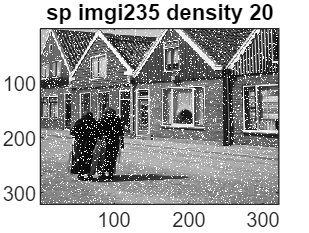


%Salt and pepper image2

img2 = double(img2);
[rr,cc]=size(img2);
maxv=max(max(img2));
indices=full(sprand(rr,cc,0.2));%0.2 is the noise density 

mask1=indices>0 & indices<0.5;  
mask2=indices>=0.5;

sp_img2 = img2.*(~mask1) ;
sp_img2 = img2.*(~mask2)+maxv*mask2;

figure, imagesc(sp_img2),colormap gray, title("sp imgi235 density 20")


## plot instogram

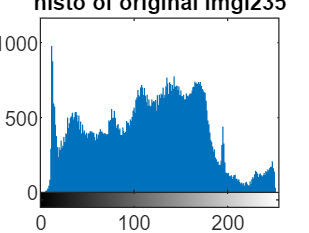

figure, imhist(uint8(img2),256), title("histo of original imgi235");


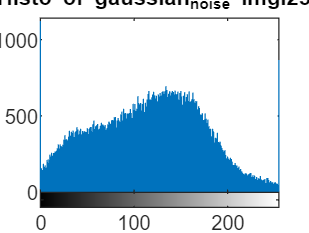

figure, imhist(uint8(gaussian_img2),256), title("Histo of gaussian_noise imgi235");


figure, imhist(uint8(gaussian_img2),256), title("Histo of gaussian_noise imgi235");

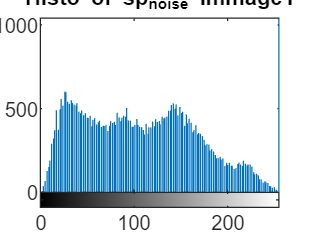

figure, imhist(uint8(sp_img1),256), title("Histo of sp_noise immage1");

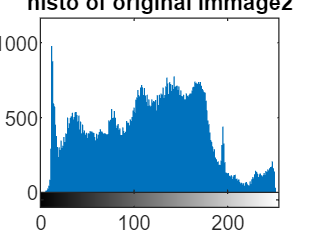

figure, imhist(uint8(img2),256), title("histo of original immage2");

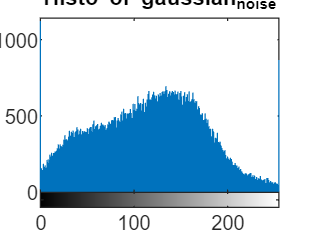

figure, imhist(uint8(gaussian_img2),256), title("Histo of gaussian_noise");

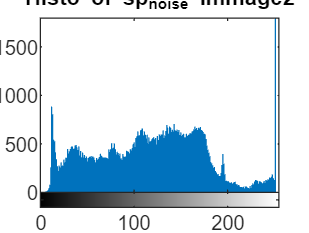

figure, imhist(uint8(sp_img2),256), title("Histo of sp_noise immage2");


## Remove noise from immage using a moving average (3x3)

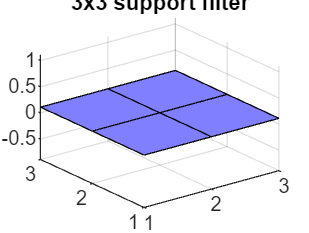

% create a 3x3 kernel matrix
A=ones(3)/9;
surf(A), colormap cool, title("3x3 support filter");

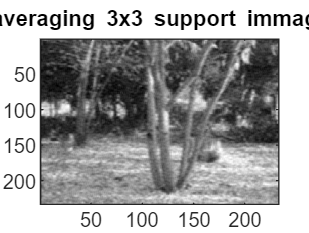

imagefilename = 'D:\Matlab\ComputerVision\ComputerVIsion\Immagini\SurfFilt3x3';
print(imagefilename, '-dpng');

% smoothing by moving averaging gaussian_noise immage1 with 3x3 kernel
out_ma1 = conv2(gaussian_img1,A,'same'); % convolution between immage with gaussian noise and k matrix
figure,imagesc(out_ma1),colormap gray,title('smoothing by averaging 3x3 support immage1 gaussian_noise')

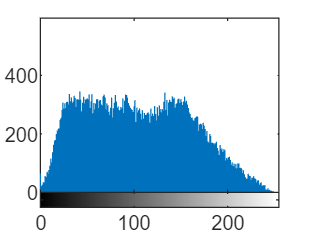


figure,imhist(uint8(out_ma1),256)

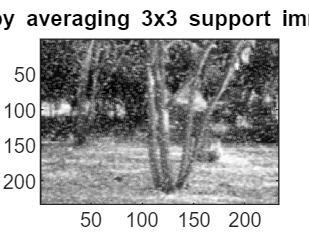


% smoothing by averaging sp_noise immage1 3x3 kernel
out_ma2=conv2(sp_img1,A,'same');
figure,imagesc(out_ma2),colormap gray,title('smoothing by averaging 3x3 support immage1 sp_noise')

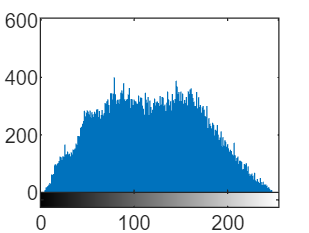

figure,imhist(uint8(out_ma2),256)

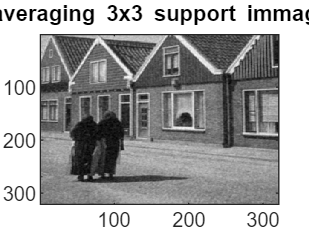


% smoothing by averaging gaussian_noise immage2 with 3x3 kernel
out_ma3=conv2(gaussian_img2,A,'same');
figure,imagesc(out_ma3),colormap gray,title('smoothing by averaging 3x3 support imgi235 gaussian_noise')

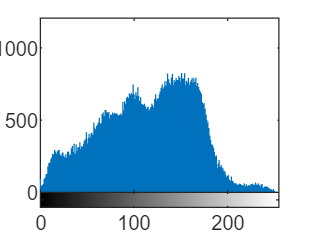

imagefilename = 'D:\Matlab\ComputerVision\ComputerVIsion\Avaraginggauss3x3';
print(imagefilename, '-dpng');
figure,imhist(uint8(out_ma3),256)

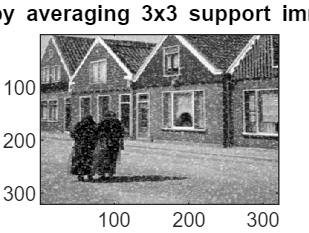

imagefilename = 'D:\Matlab\ComputerVision\ComputerVIsion\HistAvaraginggaus3x3';
print(imagefilename, '-dpng');

% smoothing by averaging sp_noise immage2 3x3 kernel
out_ma4=conv2(sp_img2,A,'same');
figure,imagesc(out_ma4),colormap gray,title('smoothing by averaging 3x3 support immage2 sp_noise')

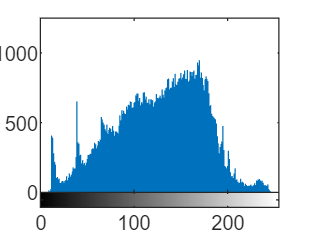

imagefilename = 'D:\Matlab\ComputerVision\ComputerVIsion\Immagini\Imspavarage 3x3';
print(imagefilename, '-dpng');
figure,imhist(uint8(out_ma4),256)

imagefilename = 'D:\Matlab\ComputerVision\ComputerVIsion\Immagini\histpavarage 3x3';
print(imagefilename, '-dpng');


## filtering using moving average (7x7)

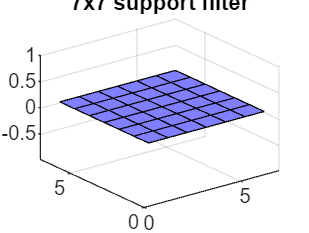

% create a 7x7 kernel matrix
A1=ones(7)/49;
surf (A1), colormap cool, title("7x7 support filter"); % plot filter

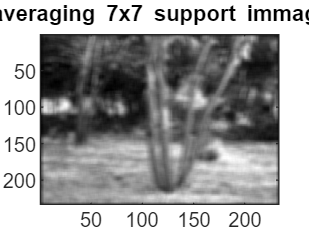



% smoothing by averaging gaussian_noise immage 1 with 7x7 kernel
out_ma5=conv2(gaussian_img1,A1,'same');
figure,imagesc(out_ma5),colormap gray,title('smoothing by averaging 7x7 support immage1 gaussian_noise')

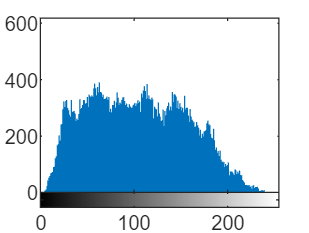

figure,imhist(uint8(out_ma5),256)

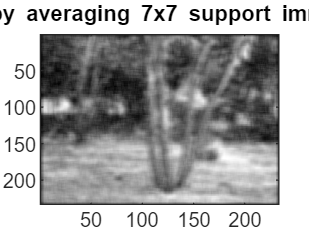


% smoothing by averaging sp_noise immage 1 7x7 kernel
out_ma6=conv2(sp_img1,A1,'same');
figure,imagesc(out_ma6),colormap gray,title('smoothing by averaging 7x7 support immage1 sp_noise')

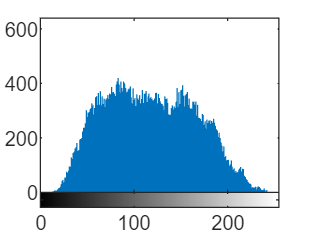

figure,imhist(uint8(out_ma6),256)

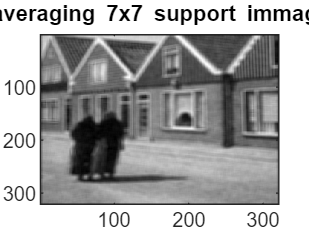


% smoothing by averaging gaussian_noise immage 2 7x7 kernel 
out_ma7=conv2(gaussian_img2,A1,'same');
figure,imagesc(out_ma7),colormap gray,title('smoothing by averaging 7x7 support immage2 gaussian_noise')

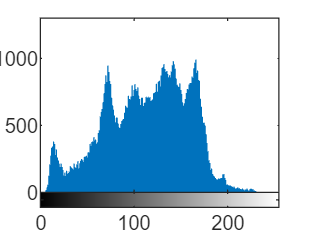

figure,imhist(uint8(out_ma7),256)

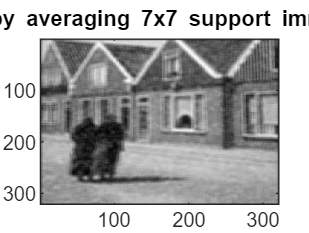


% smoothing by averaging sp_noise immage 2
out_ma8=conv2(sp_img2,A1,'same');
figure,imagesc(out_ma8),colormap gray,title('smoothing by averaging 7x7 support immage2 sp_noise')

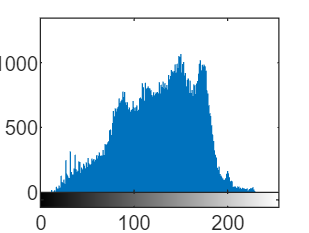

figure,imhist(uint8(out_ma8),256)

## filtering using low-pass gaussian filter for remove noise and define the contour of immage

gaussian LPF with 3x3 support

% built gausian filter 3x3 pixel support
% put sigma half-dimension of filter/3
sigma = (3/2)/3

sigma = 0.5000

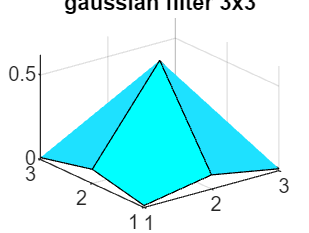

LP = fspecial('gaussian',3,sigma);

surf (LP), colormap cool, title ("gaussian filter 3x3")

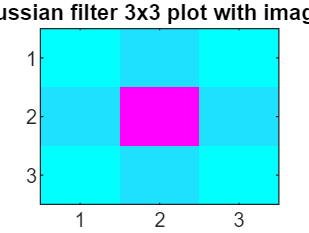

figure, imagesc(LP), colormap cool, title("gaussian filter 3x3 plot with imagesc")

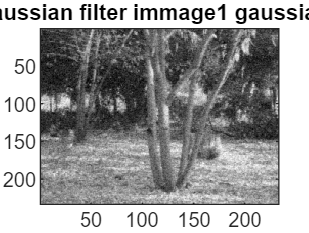


% apply gauusian filter to immage1 with gaussian_noise
out_gf = conv2(gaussian_img1, LP, 'same');
figure,imagesc(out_gf),colormap gray,title('smoothing using gaussian filter immage1 gaussian-noise 3x3 support')

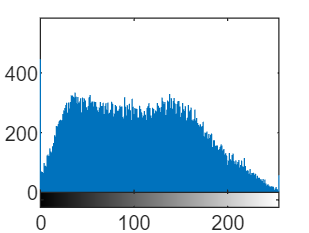

figure,imhist(uint8(out_gf),256)

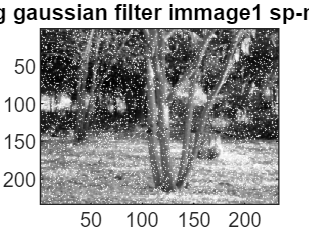


% apply gaussian filter to immage1 with sp_noise
out_gf2 = conv2(sp_img1, LP, 'same');
figure,imagesc(out_gf2),colormap gray,title('smoothing using gaussian filter immage1 sp-noise 3x3 support')

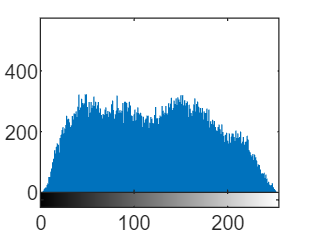

figure,imhist(uint8(out_gf2),256)

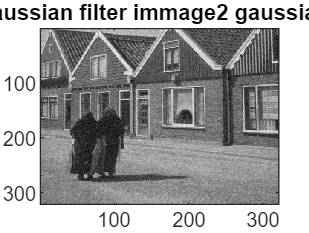


% apply gaussian filter to immage2 with gaussian_noise
out_gf3 = conv2(gaussian_img2, LP, 'same');
figure,imagesc(out_gf3),colormap gray,title('smoothing using gaussian filter immage2 gaussian-noise 3x3 support')

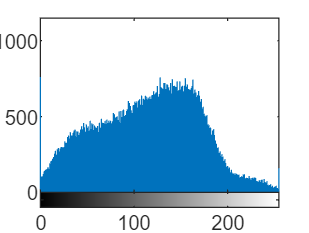

figure,imhist(uint8(out_gf3),256)

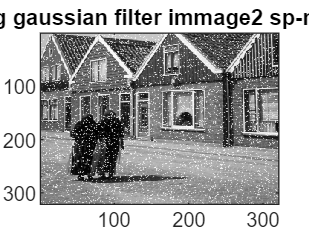


% apply gaussian filter to immage2 with gaussian_noise
out_gf4 = conv2(sp_img2, LP, 'same');
figure,imagesc(out_gf4),colormap gray,title('smoothing using gaussian filter immage2 sp-noise 3x3 support')

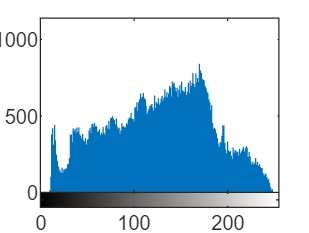

figure,imhist(uint8(out_gf4),256)

## filter using low-pass gaussian filter (7x7 pixel)

gaussian LPF with support 7x7

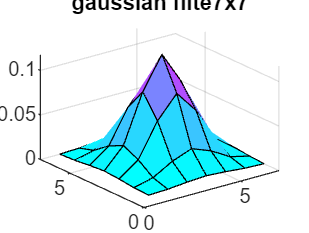

% built gaussian filter 7x7 pixel support
sigma1 = (7/2)/3;
LP1 = fspecial('gaussian',7,sigma1);

surf (LP1), colormap cool, title ("gaussian filte7x7")

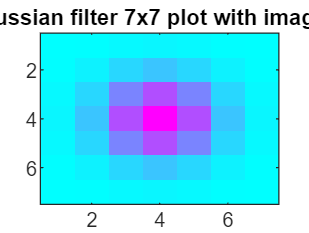

figure, imagesc(LP1), colormap cool, title("gaussian filter 7x7 plot with imagesc")

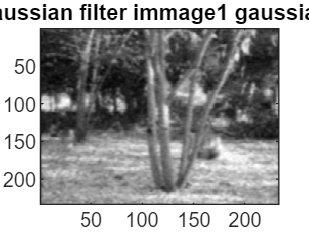


% apply gaussian filter to immage1 with gaussian_noise
out_gf5 = conv2(gaussian_img1, LP1, 'same');
figure,imagesc(out_gf5),colormap gray,title('smoothing using gaussian filter immage1 gaussian-noise 7x7 support')

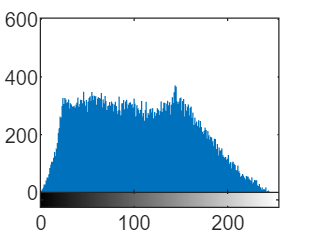

figure,imhist(uint8(out_gf5),256)

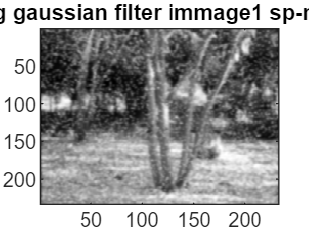


% apply gaussian filter to immage1 with sp_noise
out_gf6 = conv2(sp_img1, LP1, 'same');
figure,imagesc(out_gf6),colormap gray,title('smoothing using gaussian filter immage1 sp-noise 7x7 support')

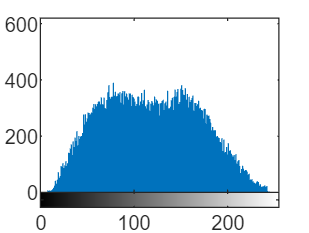

figure,imhist(uint8(out_gf6),256)

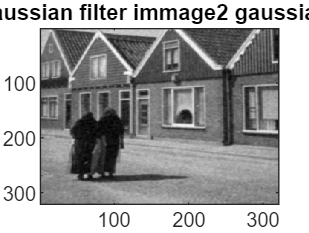


% apply gaussian filter to immage2 with gaussian_noise
out_gf7 = conv2(gaussian_img2, LP1, 'same');
figure,imagesc(out_gf7),colormap gray,title('smoothing using gaussian filter immage2 gaussian-noise 7x7 support')

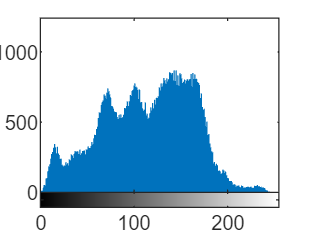

figure,imhist(uint8(out_gf7),256)

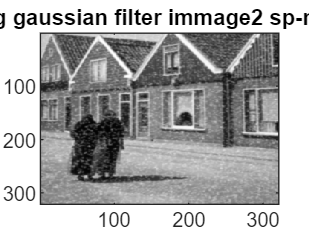


% apply gaussian filter to immage2 with gaussian_noise
out_gf8 = conv2(sp_img2, LP1, 'same');
figure,imagesc(out_gf8),colormap gray,title('smoothing using gaussian filter immage2 sp-noise 7x7 support')

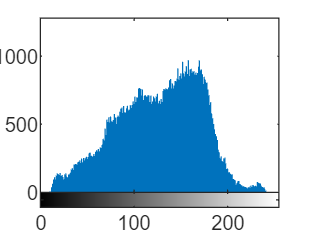

figure,imhist(uint8(out_gf8),256)

## filter using median filter (3x3)

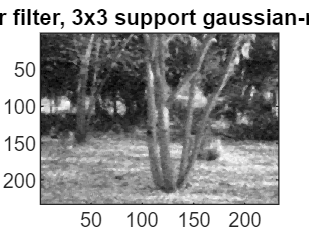

% median filter 3x3 pixel support, gaussian_noise immage1
out_m=medfilt2(gaussian_img1,[3,3]);
figure,imagesc(out_m),colormap gray,title('non-linear filter, 3x3 support gaussian-noise img1')

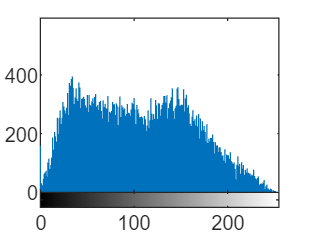

figure,imhist(uint8(out_m),256)

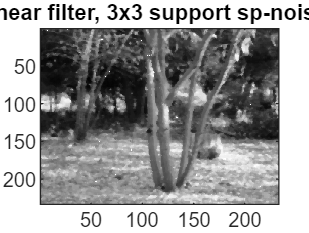


% median filter 3x3 pixel support, sp_noise immage1
out_m2=medfilt2(sp_img1,[3,3]);
figure,imagesc(out_m2),colormap gray,title('non-linear filter, 3x3 support sp-noise img1')

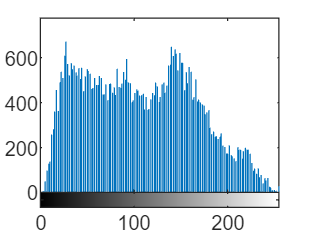

figure,imhist(uint8(out_m2),256)

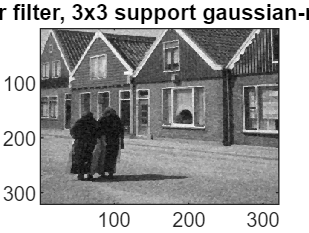


% median filter 3x3 pixel support, gaussian_noise immage1
out_m3=medfilt2(gaussian_img2,[3,3]);
figure,imagesc(out_m3),colormap gray,title('non-linear filter, 3x3 support gaussian-noise img2')

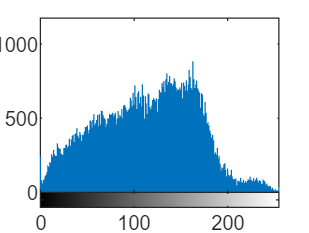

figure,imhist(uint8(out_m3),256)

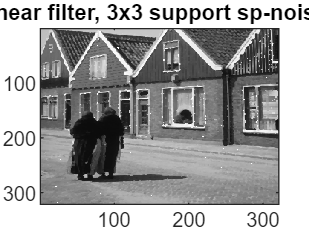


% median filter 3x3 pixel support, sp_noise immage1
out_m4=medfilt2(sp_img2,[3,3]);
figure,imagesc(out_m4),colormap gray,title('non-linear filter, 3x3 support sp-noise img2')

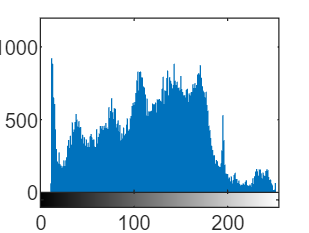

figure,imhist(uint8(out_m4),256)

## filter usando il median filter (7x7)

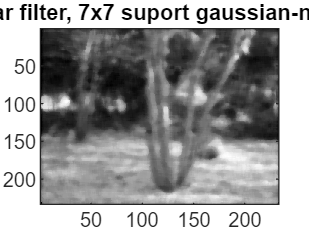

% median filter 7x7 pixel support, sp_noise immage1
out_m5=medfilt2(gaussian_img1,[7,7]);
figure,imagesc(out_m5),colormap gray,title('non-linear filter, 7x7 suport gaussian-noise img1')

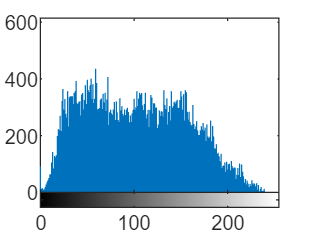

figure,imhist(uint8(out_m5),256)

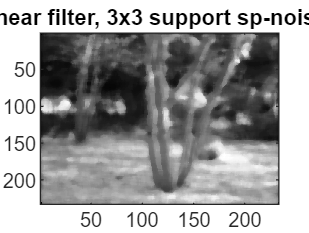


% median filter 7x7 pixel support, sp_noise immage1
out_m6=medfilt2(sp_img1,[7,7]);
figure,imagesc(out_m6),colormap gray,title('non-linear filter, 3x3 support sp-noise img1')

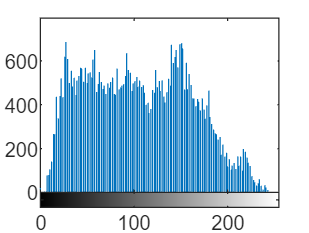

figure,imhist(uint8(out_m6),256)

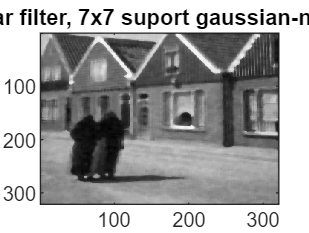


% median filter 7x7 pixel support, sp_noise immage2
out_m7=medfilt2(gaussian_img2,[7,7]);
figure,imagesc(out_m7),colormap gray,title('non-linear filter, 7x7 suport gaussian-noise img2')

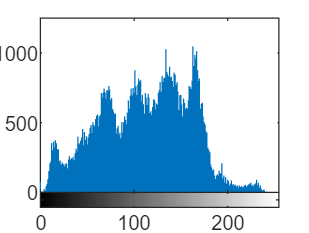

figure,imhist(uint8(out_m7),256)

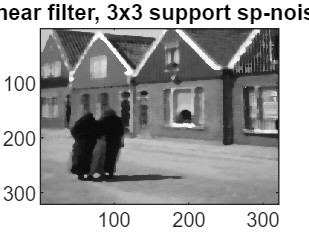


% median filter 7x7 pixel support, sp_noise immage2
out_m8=medfilt2(sp_img2,[7,7]);
figure,imagesc(out_m8),colormap gray,title('non-linear filter, 3x3 support sp-noise img2')

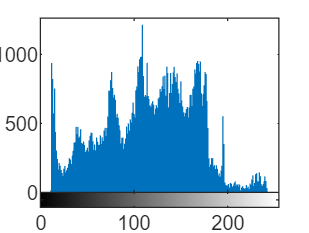

figure,imhist(uint8(out_m8),256)

## implement the slides 41-45 (practice with linear filters)

primo filtro slides 41

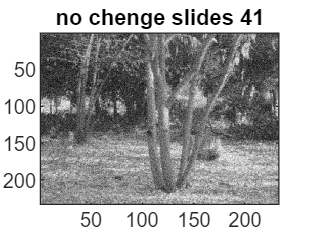

B = zeros(7);
B(4,4) = 1;

out1 = conv2(gaussian_img1, B, 'same');
figure, imagesc(out1),colormap gray, title ('no chenge slides 41')

1 pixel left shift

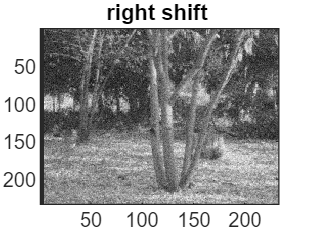

C = zeros(7);
C (4,7) = 1;

out2 = conv2(gaussian_img1, C,'same');
figure, imagesc(out2),colormap gray, title ('right shift ')

sharpening filter, slides 44

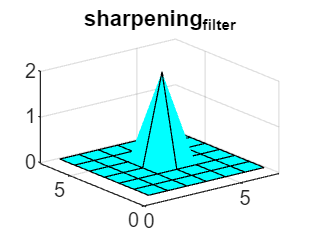

sharpening_filter = (2 * B) - A1;
surf (sharpening_filter), colormap cool, title ("sharpening_filter");

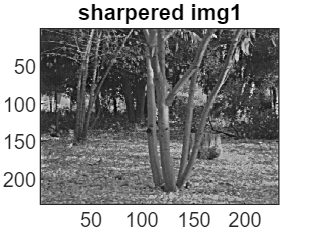

sharpered_image1 = conv2(img1, sharpening_filter, 'same');
figure, imagesc(sharpered_image1), colormap gray, title("sharpered img1")

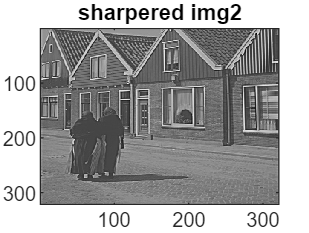


sharpered_image2 = conv2(img2, sharpening_filter, 'same');
figure, imagesc(sharpered_image2), colormap gray, title("sharpered img2")

slides 44, find only detail image1

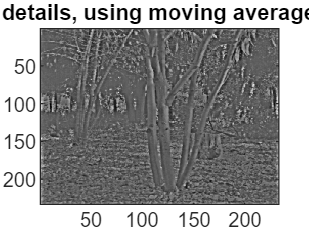

% filtering with moving average (3x3)
smooted_image1 = conv2(img1, A1, 'same');
detail_img1 = img1 -  smooted_image1;
figure, imagesc (detail_img1), colormap gray, title('only details, using moving average filter');

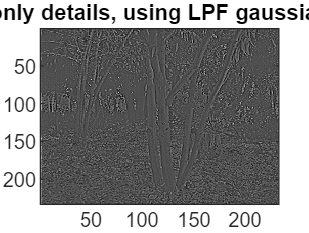

% filtering with LPF gaussian filter (3x3)
smooted_image1_1 = conv2(img1, LP, 'same');
detail_img1_1 = img1 -  smooted_image1_1;
figure, imagesc (detail_img1_1), colormap gray, title('only details, using LPF gaussian');

slides 44, find only detail image2

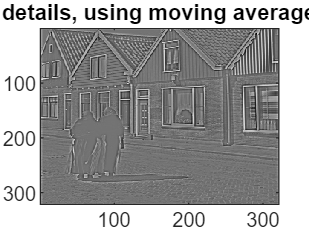

smooted_image2= conv2(img2, A1, 'same');
detail_img2 = img2 -  smooted_image2;
figure, imagesc (detail_img2), colormap gray, title('only details, using moving average filter');

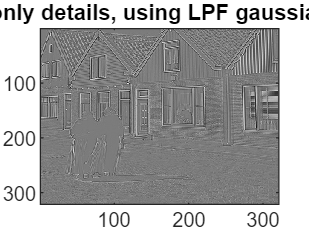

smooted_image2_1 = conv2(img2, LP, 'same');
detail_img2_1 = img2 -  smooted_image2_1;
figure, imagesc (detail_img2_1), colormap gray, title('only details, using LPF gaussian');

slide 44, plot sharpened img1 

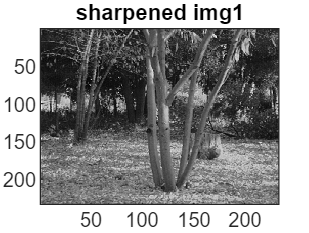

sharpened_immage1 = img1 + 2*detail_img1_1;
figure, imagesc (sharpened_immage1), colormap gray, title("sharpened img1")

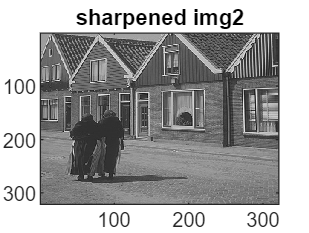

%sharpened image 2
sharpened_immage2 = img2 + 2*detail_img2_1;
figure, imagesc (sharpened_immage2), colormap gray, title("sharpened img2")

fourier transform

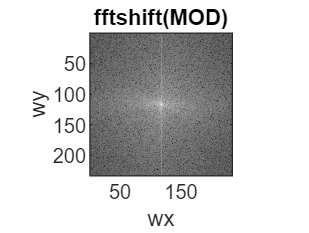

img1_fft = fft2(img1);
module_img1 = abs(img1_fft);
phi_img1 = angle(img1_fft);

%figure,imagesc(img), colormap gray,axis square

figure,imagesc(log(fftshift(module_img1))), colormap gray,xlabel('wx'),ylabel('wy'),axis square, title("fftshift(MOD)")

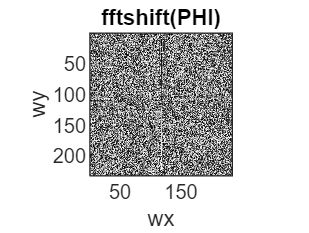


figure,imagesc(fftshift(phi_img1)), colormap gray,xlabel('wx'),ylabel('wy'),axis square, title("fftshift(PHI)")

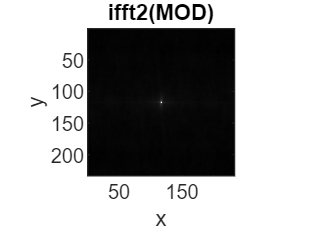


figure,imagesc(real(fftshift((ifft2(module_img1))))), colormap gray,xlabel('x'),ylabel('y'),axis square, title("ifft2(MOD)")

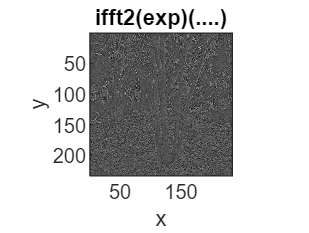


figure,imagesc(real((ifft2(exp(i*phi_img1))))), colormap gray,xlabel('x'),ylabel('y'),axis square, title("ifft2(exp)(....)")

Displey the magnitude of the fft of the gaussian LPF 

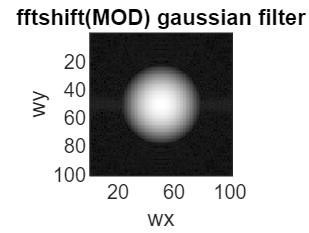

LP2 = fspecial('gaussian',101,5);
LP2_fft = fft2(LP2);
LP2_module = abs(LP2_fft);

figure,imagesc(log(fftshift(LP2_module))), colormap gray,xlabel('wx'),ylabel('wy'),axis square, title("fftshift(MOD) gaussian filter")

display a sharpering_filter inside a 101x101 zeros matrix

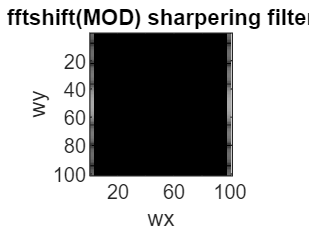

zero_matrix = zeros(101, 101);
% find the center of big matrix
center_row = ceil(size(zero_matrix, 1) / 2);
center_column = ceil(size(zero_matrix, 2) / 2);
% calculate the starting_point, the row and the column
start_row = center_row - 3; 
start_column = center_column - 3;
% paste the sharpering filter matrix inside the big matrix
zero_matrix(start_row:(start_row+6), start_column:(start_column+6)) = sharpening_filter;
zero_matrix_fft = fft(zero_matrix);
zero_matrix_mod = abs(zero_matrix_fft);
figure,imagesc(log(fftshift(zero_matrix_mod))), colormap gray,xlabel('wx'),ylabel('wy'),axis square, title("fftshift(MOD) sharpering filter")